% Plot graphs
Plot = false;

% Determine where your m-file's folder is
folder = fileparts(which("opt_problem.mlx")); 
% Add that folder plus all subfolders to the path
addpath(genpath(folder));

GFDM parameters

gfdm = struct;
gfdm.K = 8; % Subcarriers
gfdm.M = 4; % Subsymbols

gfdm.K_on = 3;
gfdm.M_on = 3;

gfdm.CP = 0; % CP length

B = 80; % Bandwidth

Es = 1; % Symbol energy

gfdm = GFDM_init(gfdm);

D = gfdm.D;
D_prime = gfdm.D_prime;

Normalized frequency $f$ and normalized frequency interval $\Delta f$

delta_f = 0.01;     % Normalized frequency: f = F/Fs = F/2B = F*Ts
f_range_end = 0.5;   % rc filter limit

% f_range_end should be divisible by delta_f
if mod(f_range_end,f_range_end)
    msg = 'normalized frequency sampling interval delta_f can not equally spaces f_range';
    error(msg);
end

f_range = [0 f_range_end];
f = -f_range(2):delta_f:f_range(2);

Interpolation filter $P(f)$

P = rc_filter(delta_f, f_range, 0.1);

Optimization problem & Dottorro iterative algorithm


$$\mathbf{S}=\mathbf{g}\mathbf{g}^H$$


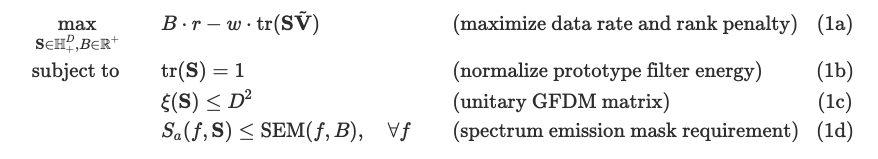

for k0 = 7:7
    %for m0 = 0:gfdm.M-1
        m0 = 1;

        k_set_temp = circshift(0:gfdm.K-1, - k0);
        k_set = k_set_temp(1:gfdm.K_on)

        m_set_temp = circshift(0:gfdm.M-1, - m0);
        m_set = m_set_temp(1:gfdm.M_on)

        s_2 = 1;
        w = 1;  % Rank 1 penalty
        V_tilde = zeros(D);
        counter = 1;

        while abs(s_2) > 10^-6
            tic
            cvx_begin sdp quiet
            variable S(D, D) hermitian nonnegative semidefinite
            expression psd_temp(length(P), 1)

            % SEM
            mask_ac_dB = ac(delta_f, f_range, B, 80);
            mask_ac_linear = db2pow(mask_ac_dB);

            % PSD
            psd = (P.^2) .* PSD_S(S, f_range, psd_temp, gfdm.K, gfdm.M, k_set, m_set, gfdm.CP, delta_f, Es);


            minimize -B + trace(S * V_tilde)   % (1a)
            subject to
            trace(S) == 1;                       % (1b)
            nep_S(S, gfdm.K, gfdm.M) <= D^2;     % (1c)
            psd <= mask_ac_linear;               % (1d)

            cvx_end
            toc

k_set =      7     0     1


m_set =      1     2     3


Elapsed time is 8.613783 seconds.


Elapsed time is 10.692555 seconds.


Elapsed time is 11.578711 seconds.


Elapsed time is 11.063730 seconds.


Elapsed time is 11.521304 seconds.


Elapsed time is 11.687345 seconds.


Elapsed time is 11.458695 seconds.


Elapsed time is 15.243948 seconds.


Elapsed time is 9.225106 seconds.


Elapsed time is 11.931354 seconds.


$\tilde{\mathbf{V}}=\mathbf{U}\mathbf{U}^H, \mathbf{U} $ is $\mathbf{Q}$ with first column removed.

$\tilde{\mathbf{V}}$represents the (D-1)-dimensional space orthogonal to the principal eigenvector of $\mathbf{S}$ in the previous iteration.

            try
                [U_svd, S_svd, ~] = svd(S);
            catch ME
                fprintf('Infeasible.\n\n');
                break;
            end

            s_2 = S_svd(2, 2);
            fprintf('%d.s_2 = %f\n\n', counter, s_2);

1.s_2 = 0.210873



2.s_2 = 0.093761



3.s_2 = 0.093073



4.s_2 = 0.093021



5.s_2 = 0.092989



6.s_2 = 0.092959



7.s_2 = 0.092929



8.s_2 = 0.091995



9.s_2 = 0.016019



10.s_2 = 0.000000




            U = U_svd(:, 2:end);
            V_tilde = U*U';

            counter = counter + 1;

Plot $S_a(f, \mathbf{S})$ and SEM

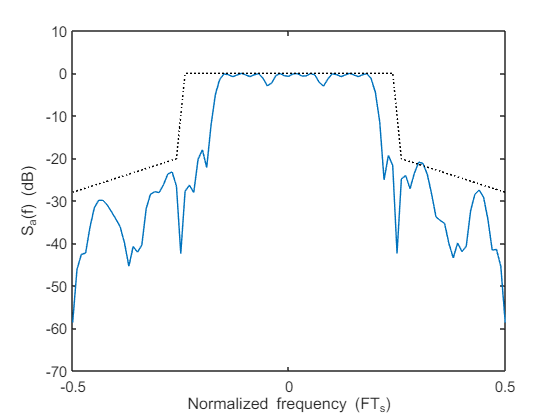

            if Plot == 1
                g = U_svd(:, 1) .* sqrt(S(1, 1));
                G = g2chaG(g, gfdm.K, gfdm.M);
                S_a = PSD(G, B, f_range, gfdm.K, gfdm.M, k_set, m_set, gfdm.CP, delta_f, Es);
                plot_PSD((P.^2) .* S_a, mask_ac_linear, f_range);
            end
        end

        if abs(s_2) < 10^-6 

            g = U_svd(:, 1) .* sqrt(S(1, 1));
            G = g2chaG(g, gfdm.K, gfdm.M);
            S_a = PSD_S(S, f_range, psd_temp, gfdm.K, gfdm.M, k_set, m_set, gfdm.CP, delta_f, Es);
            plot_PSD((P.^2) .* S_a, mask_ac_linear, f_range);
        end
    %end
end

Obtain the GFDM prototype filter $\mathbf{g}$

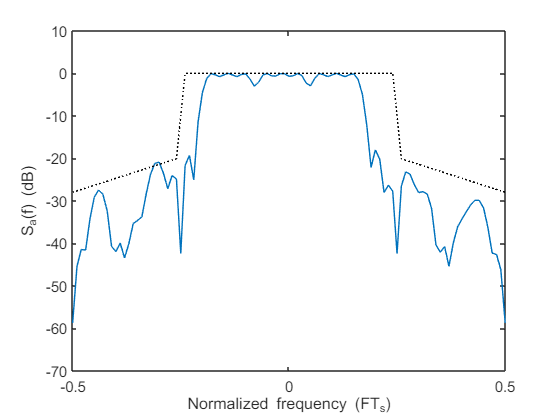

g = U_svd(:, 1) .* sqrt(S(1, 1));

psd_temp = zeros(size(P));
S_a = PSD(G, B, f_range, gfdm.K, gfdm.M, k_set, m_set, gfdm.CP, delta_f, Es);
S_a_S = PSD_S(S, f_range, psd_temp, gfdm.K, gfdm.M, k_set, m_set, gfdm.CP, delta_f, Es);
plot_PSD((P.^2) .* S_a, mask_ac_linear, f_range);